# Solutions to Coding Problems

## Exercise 11.1

### Part 2: Add varying density


clf
% We chose boat 2, which has a width of deck width of 1m, a deck height of
% 0.5m, a length of 0.6m, and a bottom hull shape of D(2x/W)^2 and a
% density (rho) of 250 kg/m^3
W = 5; % Width [m]
H = 3; % Depth [m]
L = 0.6; % Length (of extrusion) [m]

% Filament densities
rho80 = 0.8*1250;      % 100% infill [kg/m^3]
rho30 = 0.3 * 1250; %  50% infill [kg/m^3]
h = 1;           % Height of change of infill [m]

% Create density function
fun_rho = @(y) rho80 * (y < h) + rho30 * (y >= h);

% Generate grid of points
Npts = 200; % number of 1D spatial points (probably don't change)
xPoints = linspace(-W/2,W/2,Npts); % set of points in the x direction (horizontal)
zPoints = linspace(0,H,Npts); % set of points in the z direction (vertical)

[X, Z] = meshgrid(xPoints, zPoints); % create the meshgrid
P = [X(:)'; Z(:)'];

% Find interior points
insideBoat = transpose(P(2,:) >= H-(sqrt(2*pi)*exp(-(P(1,:).^2./2))) & P(1,:) <= H);
% Compute area elements
deltaA = (xPoints(2) - xPoints(1)) * (zPoints(2) - zPoints(1));

% Use the density function to vary the infill
masses = insideBoat .* fun_rho(P(2, :)') * deltaA * L;

% Compute the COM
CoM = (P*masses)/(dot(ones(size(masses)), masses))

CoM =    -0.0000
    1.9694


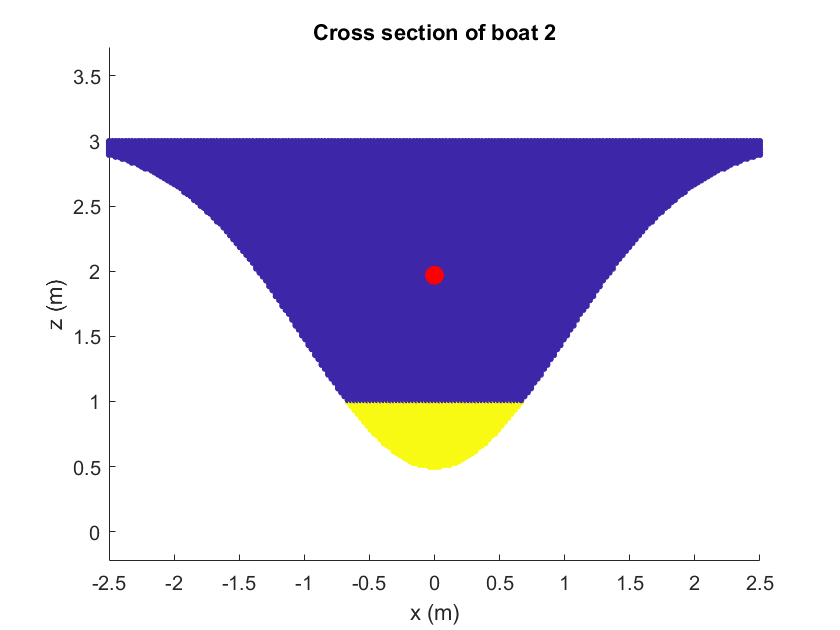


% plot only the points that are in the boat
clf
scatter(P(1,insideBoat), P(2,insideBoat), 10, masses(insideBoat), "filled"); hold on;
plot(CoM(1), CoM(2), "r.", 'MarkerSize', 32)
xlabel('x (m)');
ylabel('z (m)');
title('Cross section of boat 2');
axis equal;

### Part 3: Compute displacement ratio

rho_water = 1000; % density of water [kg/m^3]
masses_water = insideBoat * rho_water * deltaA * L;

mass_boat = sum(masses);
mass_water = sum(masses_water);

displacement_ratio = mass_boat / mass_water

displacement_ratio = 0.4197

### Part 6: Test displacement at different angles

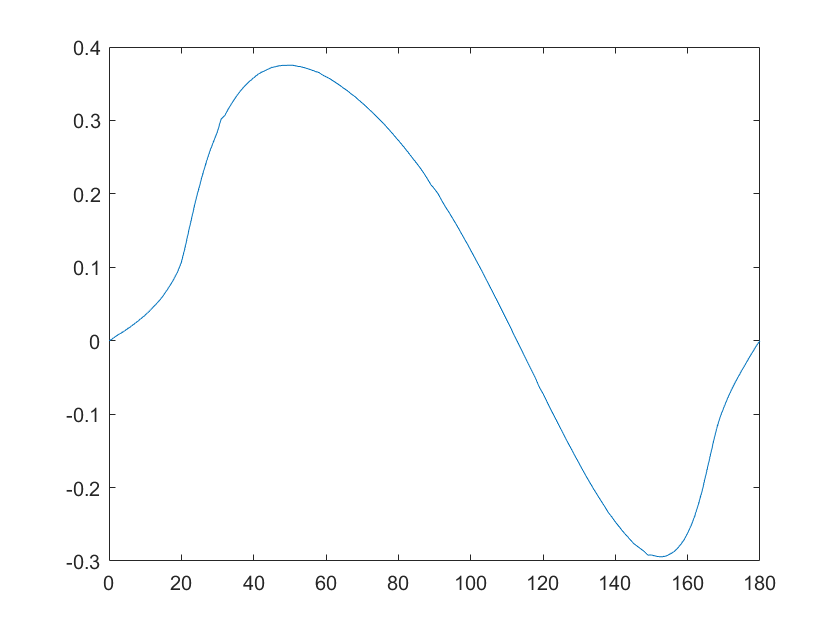

maxdisp = sum(masses_water); % find the maximum displacement
boatdisp = displacement_ratio*maxdisp;
%% main loop over the heel angles
dtheta = 1; % define the angle step
R = [cosd(dtheta) sind(dtheta); -sind(dtheta) cosd(dtheta)]; % define rotation matrix
j = 1; % set the counter
for theta = 0:dtheta:180 % loop over the angles
    [waterline, moment_arm]=  tilt(P, insideBoat, rho_water, deltaA, L, CoM, boatdisp);
    line(j)= waterline;
    marm(j) = moment_arm;
    angle(j) = theta; % define the angle
    P = R*P; % rotate the boat a little
    CoM = R*CoM; % rotate the center of mass too
    j = j + 1; % update the counter
end

AVS = avsFinder(marm)

AMV = 113.5000

function [AVS] = avsFinder(moment_arm)
    close = moment_arm(40:140);
    [d ix] = min(abs(close));
    val = close(ix-1:ix+1);
    a1 = find(moment_arm==val(1));
    a2 = find(moment_arm ==val(2));
    AVS = (a1+a2)/2;
end